% Ver sort by sort

sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
cores = [ 'r' 'b' 'g']

cores = 'rbg'

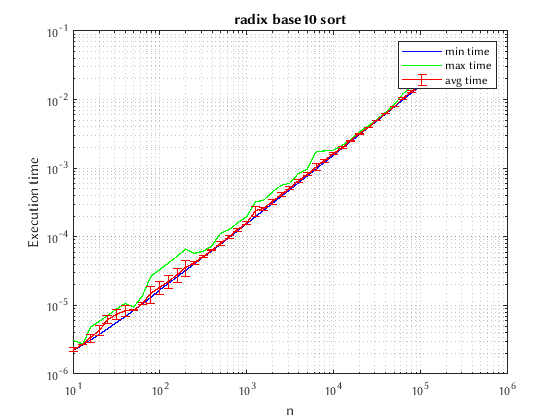

s = 6;                                                          % escolher posição do sort no array k se pretende avaliar
for s = 1:6
  a = figure(1);
  results = load(strcat(sorts(s),"_sort"));
  for k = 2:3
      loglog(results(:,1),results(:,k),cores(k),'LineStyle','-', 'Color', cores(k),'linewidth', 1);
      hold on;
  end

  errorbar(results(:,1),results(:,4),results(:,5),'LineStyle','-', 'Color', cores(1),'linewidth', 1);               % std dev no avg time

  hold off;
  %ax = axes;
  %ax.ColorOrder = [1 0 0; 0 1 0; 0 0 1; 0 0 0];
  grid("minor");
  xlabel("n");
  ylabel("Execution time");
  legend("min time","max time","avg time");
  title(strrep(strcat(sorts(s),"_sort"),"_"," "));
  saveas(gcf,strcat(sorts(s),".png"));
end

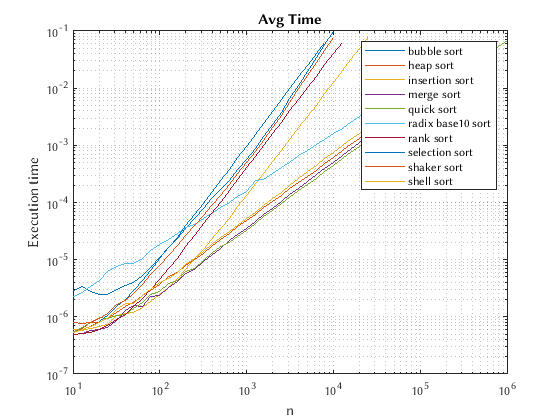

% Comparar tds os sorts

sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
data = ["Min time","Max time" ,"Avg Time"];
d = 3;                                                                  % escolher o indice da data k se pretende comparar 

for s = sorts
    results = load(strcat(s,"_sort"));
    loglog(results(:,1),results(:,d + 1));
    hold on;
end

hold off;
grid("minor");
xlabel("n");
ylabel("Execution time");
legend(strrep(strcat(sorts,"_sort"),"_"," "));
title(data(d));
saveas(gcf,"AvgTime.png")